clc; clear;
n = 10; %cantidad de funciones
m = randi([-7,7],4,n);
%m = [1,0;5,1;1,2;0,5];
dx = 0.1;
xs = -2*pi:dx:2*pi;
ys = 5*sinc(xs)
plot(xs,ys,'g', 'LineWidth',2);
for i = 1:n
    x = m([1,3],i);
    y = m([2,4],i);
    plot(x,y,'LineWidth',2); grid;
    hold on
end
for i = 1:length(x)-1
    recta1 = [xs(i),ys(i),xs(i+1),ys(i+1)];
    for i = 1:length(x)-1
    recta1 = [xs(i),ys(i),xs(i+1),ys(i+1)];
    end
end

% plot(x0,y0,'ks',"LineWidth",2,'MarkerSize',16);
% valido
% plot(x0,y0,'ks',"LineWidth",2,'MarkerSize',6);
cruces = 0;
for i=1:n-1 % barrido de rectas
    for j=i+1:n %barrido de recta2
        recta1 = m(:,i);
        recta2 = m(:,j);
        [x0,y0,valido] = cruce(recta1,recta2);
        if valido
          plot(x0,y0,'ks','LineWidth',2,'MarkerSize',6);
           cruces = cruces+1;
           
           
        end
    end
end


hay 0 cruce(s) 


disp(['hay ' num2str(cruces) ' cruce(s) ']);


ys =     0.1968    0.1401    0.0676   -0.0140   -0.0971   -0.1733   -0.2349   -0.2754   -0.2899   -0.2760   -0.2340   -0.1671   -0.0809    0.0169    0.1169    0.2095    0.2851    0.3355    0.3545    0.3389    0.2887    0.2071    0.1007   -0.0211   -0.1471   -0.2649   -0.3625   -0.4291   -0.4563   -0.4391   -0.3766   -0.2721   -0.1334    0.0282    0.1981    0.3601    0.4976    0.5952    0.6400    0.6234    0.5415    0.3968    0.1974   -0.0424   -0.3032   -0.5620   -0.7933   -0.9711   -1.0716   -1.0740


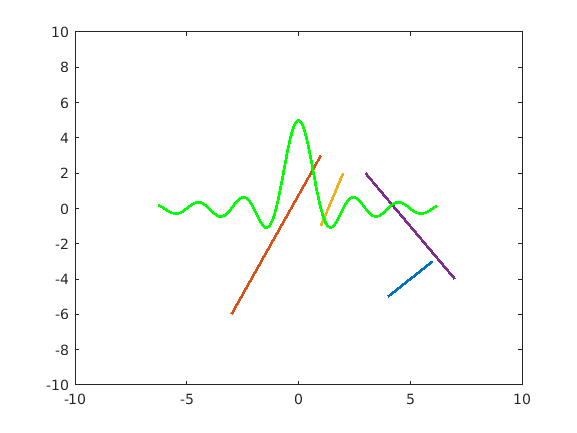


axis([-10 10 -10 10]);

hold off
